对隐函数$\mathrm{Func}\left(X,Y\right)=0$在指定范围内作图

函数作图工具有很多，但大多并不能实现数学上定义的完整函数图像——标定所有满足方程的点集。对于单值函数，作图工具往往采取遍历定义域的方式求值作图，但对于离散点、断点、渐近线往往难以处理。对于多值函数和隐函数，大多数只能作出常见的如圆、椭圆等隐函数的图像。只有本工具，采用精心设计的全平面遍历、近似判断和点线判断算法，能够完整作出给定分辨率下符合数学完整定义的的图像。如果你对本工具的强大有所怀疑，可以尝试下面提供的例子，用本工具作$x^y =y^x$的图像（需要考虑复数相等值）。你会发现，只有使用本工具的示例能够正确作出这个具有一条直线、一条曲线和两个系列的离散点的复杂图像，而无论是Win11计算器还是Wolfram Mathematica等工具，要么无法作出，要么有所遗漏！

## 语法

## 示例

在复数域绘制$x^y =y^x$

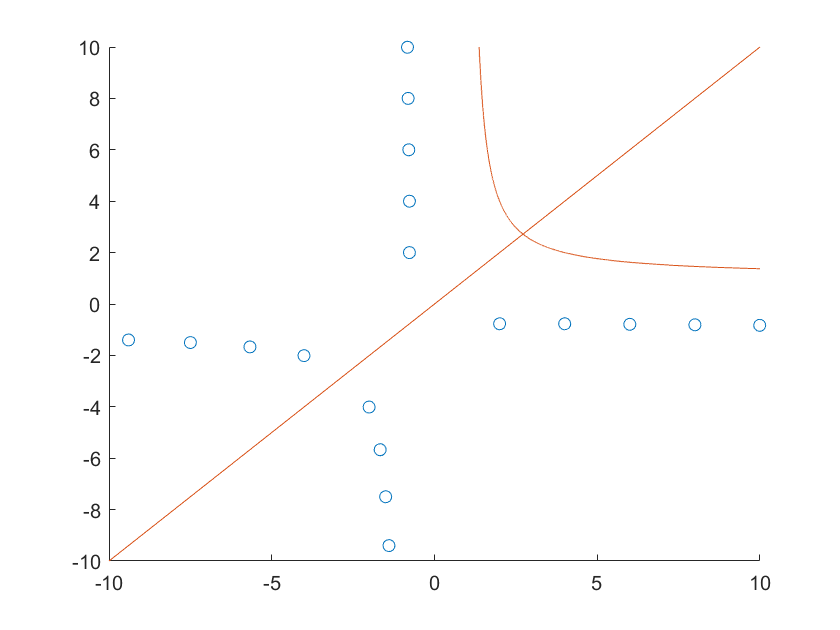

绘制$\sin \left(x\right)\sin \left(y\right)=1$，将散点填充为黑色

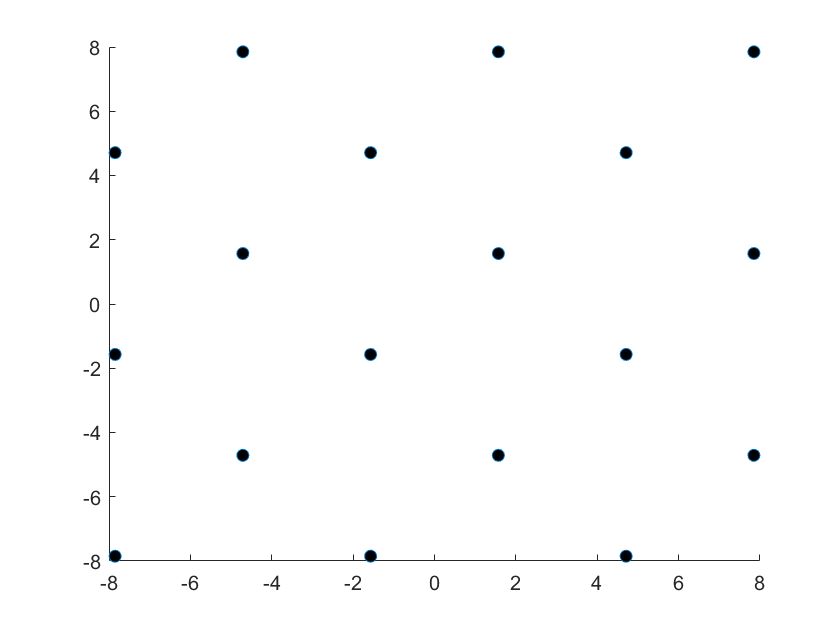

绘制$y=\tan \left(x\right)$，使用黑色线条

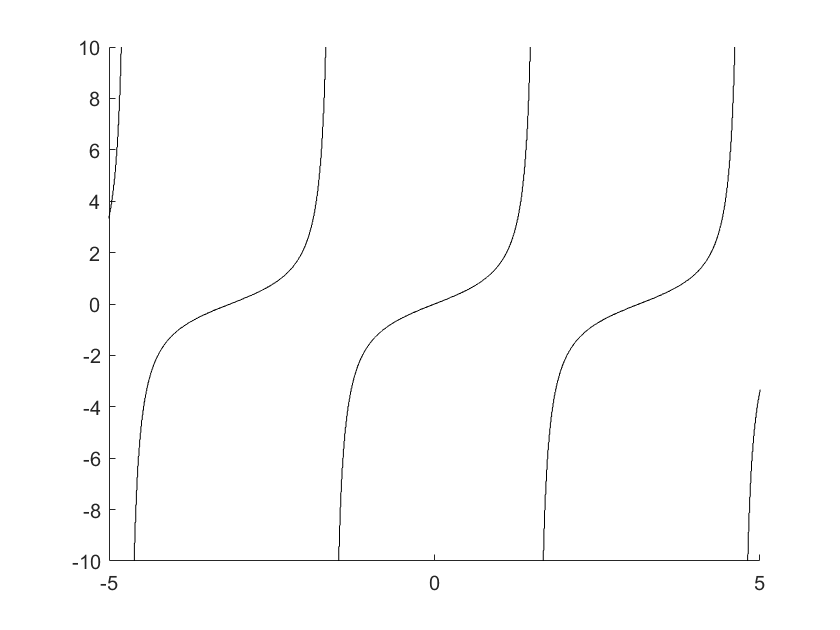

## 输入参数

Func function_handle，必须具有签名Z=Func(X,Y)，X Y Z均为double。将对方程$\mathrm{Func}\left(X,Y\right)=0$作图。将方程转换为函数句柄时，将你的方程中等号左边表达式减去等号右边表达式即可。例如作$\sin \left(x\right)\sin \left(y\right)=1$的图像，你需要输入的函数句柄是

MinX,MaxX,MinY,MaxY(1,1)，采样XY的上下限。此函数支持使用GPU加速计算，将任意参数转为gpuArray即可调用GPU计算——但前提是Func本身支持GPU计算。

Step(1,1:2)，采样步距。该数值越小，作图精度越高，但作图速度越慢；精度低则速度快，但作图质量较差，甚至可能会出现重大错误。一般建议步距在采样上下限距离的千分之一左右为好。如果输入标量，则X和Y方向采用该标量作为相同的步距。若为行向量，则第1个元素为X步距，第2个元素为Y步距。

### 名称值参数

LineThreshold(1,1)=5，点线阈值。如果一条线的长度小于这个阈值，将作为离散点处理。如果程序没有正确识别点/线，建议先降低步距，如果效果不佳可以调整该参数。但须注意，点线识别算法并不将该阈值作为唯一考虑条件。如果调整此参数效果不佳，可以尝试将Continuous设为false。

Continuous(1,1)logical=false，连续性假设，如果设为true，程序会假设图像中不存在离散的线段，即所有线条要么是闭合曲线，要么无限延伸。所有离散的（曲）线段将被识别为孤立点。一般来说这个功能不需要开启，但在处理复变函数时，因为复数的离散零点判断十分复杂容易出错，可以尝试启用此功能

LineStyle(1,:)cell={}，此函数调用内置line作连续线图，此处输入需要交给line的其它（第3个及后续）参数，每个参数用元胞包装

ScatterStyle(1,:)cell={}，此函数调用内置scatter作连续线图，此处输入需要交给scatter的其它（第3个及后续）参数，每个参数用元胞包装

## 返回值

Line matlab.graphics.primitive.Line，代表图中所有连续线条的图形对象。如果没有连续线条，返回空对象。

Scatter matlab.graphics.chart.primitive.Scatter，代表图中所有离散点的图形对象。如果没有离散点，返回空对象。

## 已知问题

Step较大时容易出现结构性错误

复数的零点识别方法比较笨拙，经常出错

对于跳变分段函数（如round）容易在台阶之间识别出幽灵点

**See also **[line](matlab:doc line) [scatter](matlab:doc scatter)

function [Line,Scatter]=FPlot(Func,MinX,MaxX,MinY,MaxY,Step,options)
arguments
	Func(1,1)function_handle
	MinX(1,1)double
	MaxX(1,1)double
	MinY(1,1)double
	MaxY(1,1)double
	Step(1,:)double
	options.LineStyle(1,:)cell={}
	options.ScatterStyle(1,:)cell={}
	options.LineThreshold(1,1)uint8=5
	options.Continuous(1,1)logical=false
end
persistent EdgeFilter LmFilter DeDoubleFilter
if isempty(EdgeFilter)
	EdgeFilter=[1 1 1;1 0 1;1 1 1];
	LmFilter=[0 1 0;1 4 1;0 1 0];
	DeDoubleFilter=[0 1 0;1 0 1;0 1 0];
end
if isscalar(Step)
	[StepX,StepY]=deal(Step);
else
	[StepX,StepY]=deal(Step(1),Step(2));
end
%扩充边缘
Xs=MinX-StepX*2:StepX:MaxX+StepX*2;
Ys=(MinY-StepY*2:StepY:MaxY+StepY*2)';
%遍历取值空间，生成草图
try
	Results=Func(Xs,Ys);
catch
	Results=bsxfun(Func,Xs,Ys);
end
AbsResults=abs(Results);
YLocalMin=islocalmin(AbsResults,1);
XLocalMin=islocalmin(AbsResults,2);
AbsoluteLocalMin=XLocalMin&YLocalMin;

%这里==0不能改用~，因为Results有可能是复数
ShouldPlot=Results==0|abs(imfilter(sign(Results),EdgeFilter,"symmetric"))<=4&imfilter(uint8(XLocalMin|YLocalMin),LmFilter,"symmetric")>3;

ShouldPlot(imfilter(uint8(ShouldPlot),DeDoubleFilter,"symmetric")>2)=false;
if any(ShouldPlot,"all")
	ShouldPlot=ShouldPlot|AbsResults<min(AbsResults(ShouldPlot))&AbsoluteLocalMin;
else
	ShouldPlot=AbsResults<min(StepX,StepY)&AbsoluteLocalMin;
end
%裁剪边缘，准备画图
ShouldPlot=gather(ShouldPlot(3:end-2,3:end-2));
AbsoluteLocalMin=AbsoluteLocalMin(3:end-2,3:end-2);
RawShouldPlot=ShouldPlot;
[Y,X]=find(ShouldPlot);
Xs=gather(Xs);
Ys=gather(Ys);
Xs=Xs(3:end-2);
Ys=Ys(3:end-2);
Line=MATLAB.DataTypes.ArrayBuilder(1);
Scatter=MATLAB.DataTypes.ArrayBuilder(1);
%漫步法生成线条
while any(ShouldPlot,"all")
	ThisPlot=false(size(ShouldPlot));
	[Y,X]=find(ShouldPlot,1);
	ShouldPlot(Y,X)=false;
	ThisPlot(Y,X)=true;
	[PlotHeight,PlotWidth]=size(ShouldPlot);
	[StartX,StartY]=deal(X,Y);
	if TryWalk(ShouldPlot)
		Positions=[StartX StartY;X Y];
		ShouldPlot(Y,X)=false;
		ThisPlot(Y,X)=true;
		LineLength=2;
		[CloseChecked,BackwardChecked]=deal(false);
		while true
			if LineLength==height(Positions)
				NewPositions=zeros(height(Positions)*2,2);
				NewPositions(1:LineLength,:)=Positions;
				Positions=NewPositions;
			end
			if TryWalk(ShouldPlot)
				LineLength=LineLength+1;
				Positions(LineLength,:)=[X Y];
				ShouldPlot(Y,X)=false;
				ThisPlot(Y,X)=true;
			elseif X==StartX&&Y==StartY%返回起点，说明是闭合回路，结束绘制
				break;
			elseif ~CloseChecked%尝试返回起点
				ShouldPlot(StartY,StartX)=true;
				CloseChecked=true;
			elseif ~BackwardChecked%尝试从起点逆行折返
				ShouldPlot(StartY,StartX)=false;
				[X,Y]=deal(StartX,StartY);
				CloseChecked=false;
				ForwardPositions=Positions(2:LineLength,:);
				ForwardLineLength=LineLength-1;
				Positions=Positions(1,:);
				LineLength=1;
				BackwardChecked=true;
			else
				break;
			end
		end
		if BackwardChecked
			Positions=[flipud(Positions(1:LineLength,:));ForwardPositions];
			LineLength=LineLength+ForwardLineLength;
		end
		ShouldPlot(StartY,StartX)=false;
	else%不能继续前进，说明是孤立点
		Positions=[StartX StartY];
		LineLength=1;
	end
	%尝试将线条首尾与之前绘制的线条连接，在范围5×5内搜寻
	PotentialConnection=RawShouldPlot&~ThisPlot;
	[X,Y]=deal(Positions(1,1),Positions(1,2));
	Connected=false;
	if TryWalk(PotentialConnection)
		Positions=[X Y;Positions];
		LineLength=LineLength+1;
		Connected=true;
	else
		SearchFieldX=max(1,X-2):min(PlotWidth,X+2);
		SearchFieldY=max(1,Y-2):min(PlotHeight,Y+2);
		[ReceptorY,ReceptorX]=find(PotentialConnection(SearchFieldY,SearchFieldX),1);
		if ~isempty(ReceptorX)
			X=round(mean(SearchFieldX(ReceptorX)));
			Y=round(mean(SearchFieldY(ReceptorY)));
			Positions=[X Y;Positions];
			LineLength=LineLength+1;
			Connected=true;
		end
	end
	[X,Y]=deal(Positions(LineLength,1),Positions(LineLength,2));
	if TryWalk(PotentialConnection)
		LineLength=LineLength+1;
		Positions(LineLength,:)=[X Y];
		Connected=true;
	else
		SearchFieldX=max(1,X-2):min(PlotWidth,X+2);
		SearchFieldY=max(1,Y-2):min(PlotHeight,Y+2);
		[ReceptorY,ReceptorX]=find(PotentialConnection(SearchFieldY,SearchFieldX),1);
		if ~isempty(ReceptorX)
			X=round(mean(SearchFieldX(ReceptorX)));
			Y=round(mean(SearchFieldY(ReceptorY)));
			LineLength=LineLength+1;
			Positions(LineLength,:)=[X Y];
			Connected=true;
		end
	end
	Positions=Positions(1:LineLength,:);
	EndMatrix=Positions([1 end],:);
	%将过短的线条或孤立线段（Continuous设为true条件下）作为孤立点进行绘制
	if LineLength<options.LineThreshold||~isequal(EndMatrix(1,:),EndMatrix(2,:))&&~any(EndMatrix(:,1)==PlotWidth|EndMatrix(:,2)==PlotHeight|EndMatrix==1,"all")&&~Connected&&options.Continuous
		[TpAlmY,TpAlmX]=find(ThisPlot&AbsoluteLocalMin,1);
		if isempty(TpAlmX)
			Positions=round(mean(Positions,1));
			Positions=[Xs(Positions(1,1))' Ys(Positions(1,2))];
		else
			Positions=[Xs(TpAlmX) Ys(TpAlmY)];
		end
		Scatter.Append(Positions);
	else
		%正常的线条则正常绘制
		Line.Append([Xs(Positions(:,1))',Ys(Positions(:,2));NaN,NaN]);
	end
end
	function Walked=TryWalk(Map)
		%在地图上走一步
		Walked=false;
		if X>1&&Map(Y,X-1)
			Walked=true;
			X=X-1;
		elseif X<PlotWidth&&Map(Y,X+1)
			Walked=true;
			X=X+1;
		elseif Y>1&&Map(Y-1,X)
			Walked=true;
			Y=Y-1;
		elseif Y<PlotHeight&&Map(Y+1,X)
			Walked=true;
			Y=Y+1;
		elseif X>1&&Y>1&&Map(Y-1,X-1)
			Walked=true;
			X=X-1;
			Y=Y-1;
		elseif X>1&&Y<PlotHeight&&Map(Y+1,X-1)
			Walked=true;
			X=X-1;
			Y=Y+1;
		elseif X<PlotWidth&&Y>1&&Map(Y-1,X+1)
			Walked=true;
			X=X+1;
			Y=Y-1;
		elseif X<PlotWidth&&Y<PlotHeight&&Map(Y+1,X+1)
			Walked=true;
			X=X+1;
			Y=Y+1;
		end
	end
Scatter=Scatter.Harvest;
if isempty(Scatter)
	Scatter=matlab.graphics.chart.primitive.Scatter.empty;
else
	Scatter=scatter(Scatter(:,1),Scatter(:,2),options.ScatterStyle{:});
end
Line=Line.Harvest;
if isempty(Line)
	Line=matlab.graphics.primitive.Line.empty;
else
	Line=line(Line(:,1),Line(:,2),options.LineStyle{:});
end
end